# Specify Labels at the Ends of Bars

Define `vals` as a matrix containing the values of two data sets. Display the values in a bar graph and specify an output argument. Since there are two data sets, `bar` returns a vector containing two `Bar` objects.

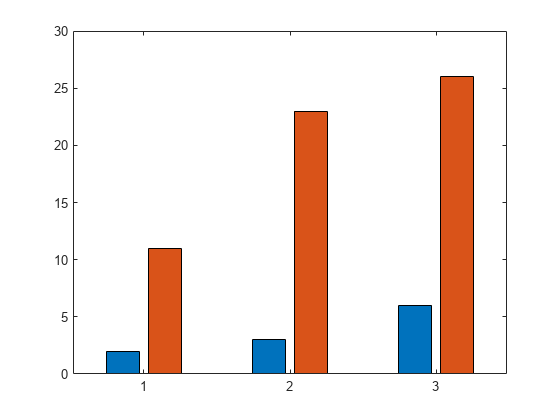

x = [1 2 3];
vals = [2 3 6; 11 23 26];
b = bar(x,vals);

Display the values at the tips of the first series of bars. Get the coordinates of the tips of the bars by getting the `XEndPoints` and `YEndPoints` properties of the first `Bar` object. Pass those coordinates to the `text` function, and specify the vertical and horizontal alignment so that the values are centered above the tips of the bars.

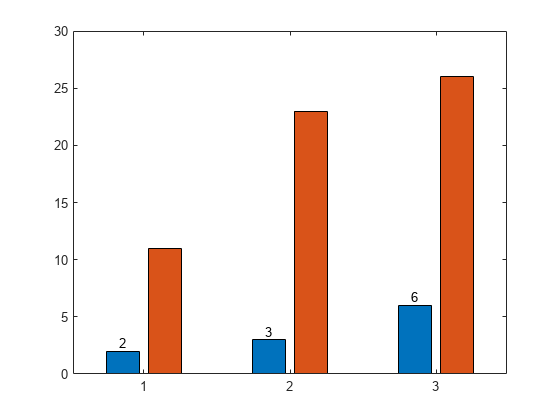

xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

Next, display the values above the tips of the second series of bars.

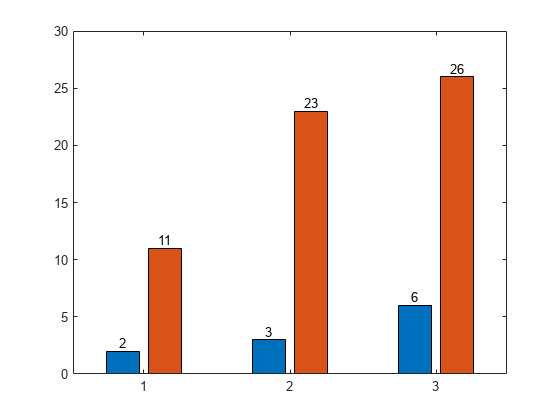

xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(b(2).YData);
text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

*Copyright 2019 The MathWorks, Inc.*